% =========================================================================
% 《电磁场理论》实验三：两个电流环在 YZ 平面上的磁场分布
% 报告人：HE Yanning, 12311512
% =========================================================================
% 实验说明：
%   两个半径 a=2 m 的圆形电流环，分别位于 z=-1 和 z=1 处（圆心在 z 轴上），
%   平行于 xy 平面放置，载有电流 I=500 A。在 YZ 平面（x=0）上计算磁场分布。
%   情形一：两个电流环电流方向相同（亥姆霍兹线圈结构）
%   情形二：两个电流环电流方向相反
% =========================================================================

clc; clear; close all;
a = 2;              % 电流环半径，单位：m
I = 500;            % 电流环中流通的电流，单位：A
C = I / (4 * pi);   % 归并常数（毕奥-萨伐尔定律中的常数因子）
N = 200;            % 将每个电流环等分成 N 段（分段数越大，计算越精确）
ym = 5;             % 场域中 y 方向的范围：[-ym, ym]
zm = 5;             % 场域中 z 方向的范围：[-zm, zm]
n = 100;            % 将 y 轴和 z 轴各等分成 n 等份（网格分辨率）

studentTag = 'HE Yanning, 12311512';  % 姓名及学号，用于图片标题

y = linspace(-ym, ym, n);       % 将 y 轴等分成 n 等份
z = linspace(-zm, zm, n);       % 将 z 轴等分成 n 等份
[Y, Z] = meshgrid(y, z);        % 生成 YZ 平面上的网格矩阵
theta0 = linspace(0, 2*pi, N+1);    % 将圆周角等分为 N+1 份
theta1 = theta0(1:N);               % 第 i 段电流元的起始角度
x1 = a * cos(theta1);               % 第 i 段电流元的起始 x 坐标
y1 = a * sin(theta1);               % 第 i 段电流元的起始 y 坐标
theta2 = theta0(2:N+1);             % 第 i 段电流元的终止角度
x2 = a * cos(theta2);               % 第 i 段电流元的终止 x 坐标
y2 = a * sin(theta2);               % 第 i 段电流元的终止 y 坐标

xc = (x1 + x2) / 2;     % 第 i 段电流元中点的 x 坐标（用于近似计算径矢）
yc = (y1 + y2) / 2;     % 第 i 段电流元中点的 y 坐标

dlx = x2 - x1;          % 第 i 段电流元矢量 dl 的 x 分量
dly = y2 - y1;          % 第 i 段电流元矢量 dl 的 y 分量
dlz = 0;                % 第 i 段电流元矢量 dl 的 z 分量（电流环在 xy 平面上，故 z 分量为 0）

% 两个电流环的圆心 z 坐标
zc1 = -1;               % 下方电流环圆心位于 z=-1
zc2 = 1;                % 上方电流环圆心位于 z=1


fprintf('正在计算情形一（电流同向，亥姆霍兹线圈）...\n');

正在计算情形一（电流同向，亥姆霍兹线圈）...


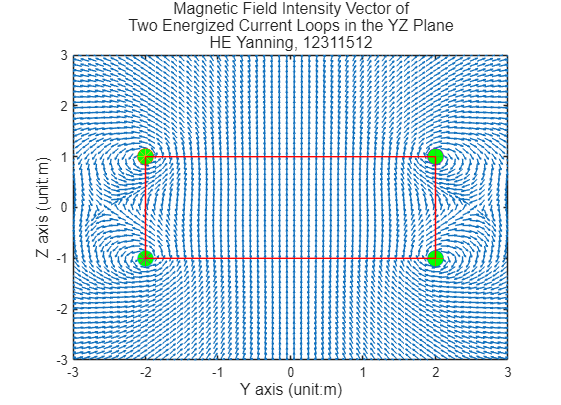


% 初始化磁场分量矩阵（全部置零）
Hy1 = zeros(n);     % 磁场强度 H 的 y 分量
Hz1 = zeros(n);     % 磁场强度 H 的 z 分量
H1  = zeros(n);     % 磁场强度 H 的大小 |H| = sqrt(Hy^2 + Hz^2)

% ---------- 利用毕奥-萨伐尔定律循环计算各网点上的 H 值 ----------
% 原理：将两个电流环各分成 N 段电流元，对每个网格点，累加所有电流元
%       在该点产生的磁场贡献。电流元 dl 在空间某点产生的磁场为：
%       dH = (I/(4*pi)) * (dl × R) / R^3
% 其中 R 为从电流元指向场点的矢量，R = |R|。
for i = 1:N
    % 观测面为 x=0 平面，所有场点的 x 坐标均为 0
    X = zeros(n);           % 场点在 x 方向上的坐标（全为零）

    rx = X - xc(i);         % 径矢 R 的 x 分量：场点 x - 电流元中点 x
    ry = Y - yc(i);         % 径矢 R 的 y 分量：场点 y - 电流元中点 y
    rz1 = Z - zc1;          % 径矢 R 的 z 分量（下方电流环）：场点 z - zc1
    rz2 = Z - zc2;          % 径矢 R 的 z 分量（上方电流环）：场点 z - zc2

    % 计算 R^3 = (rx^2 + ry^2 + rz^2)^(3/2)
    r31 = sqrt(rx.^2 + ry.^2 + rz1.^2).^3;     % 下方电流环的 R^3
    r32 = sqrt(rx.^2 + ry.^2 + rz2.^2).^3;     % 上方电流环的 R^3

    % 计算叉乘 dl × R 的各分量
    % 由于 dl = (dlx, dly, 0)，R = (rx, ry, rz)：
    %   (dl × R)_x = dly*rz - dlz*ry = dly*rz        （不为零，但观测面在 x=0 上）
    %   (dl × R)_y = dlz*rx - dlx*rz = -dlx*rz       （y 分量）
    %   (dl × R)_z = dlx*ry - dly*rx                 （z 分量）
    % 情形一中两个环电流方向相同，dl 方向相同
    dlXr_y1 = -dlx(i) .* rz1;      % 下方电流环的 (dl×R)_y
    dlXr_y2 = -dlx(i) .* rz2;      % 上方电流环的 (dl×R)_y
    dlXr_z = dlx(i) .* ry - dly(i) .* rx;  % (dl×R)_z（上、下环相同）

    % 累加各电流元的磁场贡献：H = H + C * (dl×R) / R^3
    Hy1 = Hy1 + C .* dlXr_y1 ./ r31;    % 累加下方环对 Hy 的贡献
    Hy1 = Hy1 + C .* dlXr_y2 ./ r32;    % 累加上方环对 Hy 的贡献
    Hz1 = Hz1 + C .* dlXr_z  ./ r31;    % 累加下方环对 Hz 的贡献
    Hz1 = Hz1 + C .* dlXr_z  ./ r32;    % 累加上方环对 Hz 的贡献
    H1  = (Hy1.^2 + Hz1.^2).^0.5;       % 计算合磁场大小 |H|
end

% ---------- 图1-1：全局磁场分布（三维网格图）----------
figure('Color', 'w', 'Position', [100, 100, 900, 650]);
mesh(Y, Z, H1);                          % 绘制三维网格图
hold on;
title(sprintf(['Magnetic Field Distribution of\n' ...
    'Two Energized Current Loops in the YZ Plane\n' ...
    '%s'], studentTag), 'FontSize', 12);  % 标题（含姓名学号）
axis([-5, 5, -5, 5, -50, 500]);          % 设置坐标轴范围：[y_min, y_max, z_min, z_max, H_min, H_max]
xlabel('Y axis (unit:m)', 'FontSize', 12); % y 轴标签
ylabel('Z axis (unit:m)', 'FontSize', 12); % z 轴标签
zlabel('H (unit:A/m)', 'FontSize', 12);    % H 轴标签（磁场强度大小）
saveas(gcf, 'case1_01_full_mesh.png');     % 保存图片

% ---------- 图1-2：局部磁场分布（感兴趣区域 y in [-2,2], z in [-1,1]）----------
figure('Color', 'w', 'Position', [100, 100, 900, 650]);
mesh(Y, Z, H1);                          % 绘制三维网格图
hold on;
title(sprintf(['Interested Region of Magnetic Field Distribution of\n' ...
    'Two Energized Current Loops in the YZ Plane\n' ...
    '%s'], studentTag), 'FontSize', 12);
axis([-2, 2, -1, 1, 0, 500]);            % 聚焦到感兴趣区域
xlabel('Y axis (unit:m)', 'FontSize', 12);
ylabel('Z axis (unit:m)', 'FontSize', 12);
zlabel('H (unit:A/m)', 'FontSize', 12);
saveas(gcf, 'case1_02_local_mesh.png');

% ---------- 图1-3：等磁线图 ----------
figure('Color', 'w', 'Position', [100, 100, 900, 650]);
Hmin = 0;  Hmax = 200;                  % 等磁线 H 值的最小值和最大值
H0 = linspace(Hmin, Hmax, 100);          % 将等磁线值等分为 100 级
contour(Y, Z, H1, H0);                   % 绘制等磁线图
grid on;  hold on;
title(sprintf('Isomagnetic Line on YZ Plane\n%s', studentTag), 'FontSize', 12);
axis([-5, 5, -5, 5]);
% 标注电流环剖面位置（用绿色圆点标记）
plot(-2, 1,  'o', 'MarkerFaceColor', 'g', 'MarkerSize', 12);  % 上方环左端
plot(-2, 1,  '*', 'MarkerFaceColor', 'k', 'MarkerSize', 12);  % 电流方向（* 表示流出纸面）
plot(2,  1,  'o', 'MarkerFaceColor', 'g', 'MarkerSize', 12);  % 上方环右端
plot(2,  1,  '+', 'MarkerFaceColor', 'k', 'MarkerSize', 12);  % 电流方向（+ 表示流入纸面）
plot(-2, -1, 'o', 'MarkerFaceColor', 'g', 'MarkerSize', 12);  % 下方环左端
plot(-2, -1, '*', 'MarkerFaceColor', 'k', 'MarkerSize', 12);  % 电流方向
plot(2,  -1, 'o', 'MarkerFaceColor', 'g', 'MarkerSize', 12);  % 下方环右端
plot(2,  -1, '+', 'MarkerFaceColor', 'k', 'MarkerSize', 12);  % 电流方向
rectangle('Position', [-2, -1, 4, 2], 'EdgeColor', 'r');       % 红色矩形框标记感兴趣区域
xlabel('Y axis (unit:m)', 'FontSize', 12);
ylabel('Z axis (unit:m)', 'FontSize', 12);
saveas(gcf, 'case1_03_contour.png');

% ---------- 图1-4：磁力线分布图 ----------
figure('Color', 'w', 'Position', [100, 100, 900, 650]);
% 设置磁力线起始圆的参数（在半径为 1.5 的圆上取种子点）
theta = [0 50 60 70 80 90 100 110 120 130 180] .* pi / 180;  % 种子点角度（弧度）
ys = 1.5 * cos(theta);      % 磁力线起始点的 y 坐标
zs = 1.5 * sin(theta);      % 磁力线起始点的 z 坐标
streamline(Y, Z, Hy1, Hz1, ys, zs);       % 从起始圆向外绘制磁力线
streamline(Y, Z, -Hy1, -Hz1, ys, zs);     % 从起始圆向内绘制磁力线（反方向）
title(sprintf('Magnetic Field Lines on YZ Plane\n%s', studentTag), 'FontSize', 12);
hold on;
axis([-5, 5, -5, 5]);
% 标注电流环剖面位置（同上）
plot(-2, 1,  'o', 'MarkerFaceColor', 'g', 'MarkerSize', 12);
plot(-2, 1,  '*', 'MarkerFaceColor', 'k', 'MarkerSize', 12);
plot(2,  1,  'o', 'MarkerFaceColor', 'g', 'MarkerSize', 12);
plot(2,  1,  '+', 'MarkerFaceColor', 'k', 'MarkerSize', 12);
plot(-2, -1, 'o', 'MarkerFaceColor', 'g', 'MarkerSize', 12);
plot(-2, -1, '*', 'MarkerFaceColor', 'k', 'MarkerSize', 12);
plot(2,  -1, 'o', 'MarkerFaceColor', 'g', 'MarkerSize', 12);
plot(2,  -1, '+', 'MarkerFaceColor', 'k', 'MarkerSize', 12);
rectangle('Position', [-2, -1, 4, 2], 'EdgeColor', 'r');
xlabel('Y axis (unit:m)', 'FontSize', 12);
ylabel('Z axis (unit:m)', 'FontSize', 12);
saveas(gcf, 'case1_04_streamline.png');

% ---------- 图1-5：磁场强度矢量图 ----------
figure('Color', 'w', 'Position', [100, 100, 900, 650]);
Hy1_norm = Hy1 ./ H1;       % 将 Hy 归一化（只保留方向信息）
Hz1_norm = Hz1 ./ H1;       % 将 Hz 归一化
quiver(Y, Z, Hy1_norm, Hz1_norm);        % 绘制矢量箭头图
hold on;
title(sprintf(['Magnetic Field Intensity Vector of\n' ...
    'Two Energized Current Loops in the YZ Plane\n' ...
    '%s'], studentTag), 'FontSize', 12);
axis([-3, 3, -3, 3]);        % 矢量图使用较小的坐标范围以看清箭头方向
% 标注电流环剖面位置
plot(-2, 1,  'o', 'MarkerFaceColor', 'g', 'MarkerSize', 12);
plot(-2, 1,  '*', 'MarkerFaceColor', 'k', 'MarkerSize', 12);
plot(2,  1,  'o', 'MarkerFaceColor', 'g', 'MarkerSize', 12);
plot(2,  1,  '+', 'MarkerFaceColor', 'k', 'MarkerSize', 12);
plot(-2, -1, 'o', 'MarkerFaceColor', 'g', 'MarkerSize', 12);
plot(-2, -1, '*', 'MarkerFaceColor', 'k', 'MarkerSize', 12);
plot(2,  -1, 'o', 'MarkerFaceColor', 'g', 'MarkerSize', 12);
plot(2,  -1, '+', 'MarkerFaceColor', 'k', 'MarkerSize', 12);
rectangle('Position', [-2, -1, 4, 2], 'EdgeColor', 'r');
xlabel('Y axis (unit:m)', 'FontSize', 12);
ylabel('Z axis (unit:m)', 'FontSize', 12);
saveas(gcf, 'case1_05_vector.png');


fprintf('情形一的 5 张图片已生成完毕。\n');

情形一的 5 张图片已生成完毕。



fprintf('正在计算情形二（电流反向）...\n');

正在计算情形二（电流反向）...



% 重新初始化磁场分量矩阵
Hy2 = zeros(n);
Hz2 = zeros(n);
H2  = zeros(n);

% ---------- 循环计算各网点上的 H 值 ----------
% 注意：情形二与情形一的关键区别在于上方电流环的电流方向相反，
%       即上方环的 dl 分量取反号。在计算 dl×R 时：
%       下方环的 y 分量仍为 dlXr_y1 = -dlx*rz1（与情形一相同）
%       上方环的 y 分量变为   dlXr_y2 = -(-dlx)*rz2 = +dlx*rz2（取反）
%       z 分量上方环也取反
for i = 1:N
    X = zeros(n);
    rx = X - xc(i);
    ry = Y - yc(i);
    rz1 = Z - (-1);     % 下方电流环圆心 z = -1
    rz2 = Z - 1;        % 上方电流环圆心 z = 1（此处直接用数字，避免与向量混淆）

    r31 = sqrt(rx.^2 + ry.^2 + rz1.^2).^3;
    r32 = sqrt(rx.^2 + ry.^2 + rz2.^2).^3;

    % 情形二：上方环电流方向相反 → dl 取反 → 叉乘结果也取反
    dlXr_y1 = -dlx(i) .* rz1;          % 下方环：(dl×R)_y（与情形一相同）
    dlXr_y2 = -(-dlx(i)) .* rz2;       % 上方环：(dl×R)_y（取反号！）
    dlXr_z1 = -dlx(i) .* ry + dly(i) .* rx;   % 下方环：(dl×R)_z（取反！注意与情形一的区别）
    dlXr_z2 = dlx(i) .* ry - dly(i) .* rx;    % 上方环：(dl×R)_z（与情形一相同）

    Hy2 = Hy2 + C .* dlXr_y1 ./ r31;    % 累加下方环对 Hy 的贡献
    Hy2 = Hy2 + C .* dlXr_y2 ./ r32;    % 累加上方环对 Hy 的贡献（方向相反）
    Hz2 = Hz2 + C .* dlXr_z1 ./ r31;    % 累加下方环对 Hz 的贡献（方向相反）
    Hz2 = Hz2 + C .* dlXr_z2 ./ r32;    % 累加上方环对 Hz 的贡献
    H2  = (Hy2.^2 + Hz2.^2).^0.5;       % 计算合磁场大小
end

% ---------- 图2-1：全局磁场分布（三维网格图）----------
figure('Color', 'w', 'Position', [100, 100, 900, 650]);
mesh(Y, Z, H2);
hold on;
title(sprintf(['Magnetic Field Distribution of\n' ...
    'Two Opposite-Direction Current Loops in the YZ Plane\n' ...
    '%s'], studentTag), 'FontSize', 12);
axis([-5, 5, -5, 5, -50, 500]);
xlabel('Y axis (unit:m)', 'FontSize', 12);
ylabel('Z axis (unit:m)', 'FontSize', 12);
zlabel('H (unit:A/m)', 'FontSize', 12);
saveas(gcf, 'case2_01_full_mesh.png');

% ---------- 图2-2：局部磁场分布（感兴趣区域）----------
figure('Color', 'w', 'Position', [100, 100, 900, 650]);
mesh(Y, Z, H2);
hold on;
title(sprintf(['Interested Region of Magnetic Field Distribution of\n' ...
    'Two Opposite-Direction Current Loops in the YZ Plane\n' ...
    '%s'], studentTag), 'FontSize', 12);
axis([-2, 2, -1, 1, 0, 500]);
xlabel('Y axis (unit:m)', 'FontSize', 12);
ylabel('Z axis (unit:m)', 'FontSize', 12);
zlabel('H (unit:A/m)', 'FontSize', 12);
saveas(gcf, 'case2_02_local_mesh.png');

% ---------- 图2-3：等磁线图 ----------
% 注意：情形二中上方环电流反向 → 电流方向标记与情形一不同
%       下方环：左侧 *（流出）、右侧 +（流入）→ 与情形一相同
%       上方环：左侧 +（流入）、右侧 *（流出）→ 与情形一相反！
figure('Color', 'w', 'Position', [100, 100, 900, 650]);
Hmin = 0;  Hmax = 200;
H0 = linspace(Hmin, Hmax, 100);
contour(Y, Z, H2, H0);
grid on;  hold on;
title(sprintf('Isomagnetic Line on YZ Plane\n%s', studentTag), 'FontSize', 12);
axis([-5, 5, -5, 5]);
plot(-2, 1,  'o', 'MarkerFaceColor', 'g', 'MarkerSize', 12);   % 上方环左端
plot(-2, 1,  '*', 'MarkerFaceColor', 'k', 'MarkerSize', 12);   % 电流方向（*流出）
plot(2,  1,  'o', 'MarkerFaceColor', 'g', 'MarkerSize', 12);   % 上方环右端
plot(2,  1,  '+', 'MarkerFaceColor', 'k', 'MarkerSize', 12);   % 电流方向（+流入）
plot(-2, -1, 'o', 'MarkerFaceColor', 'g', 'MarkerSize', 12);   % 下方环左端
plot(-2, -1, '+', 'MarkerFaceColor', 'k', 'MarkerSize', 12);   % 注意：下方环此处为 +（流入）
plot(2,  -1, 'o', 'MarkerFaceColor', 'g', 'MarkerSize', 12);   % 下方环右端
plot(2,  -1, '*', 'MarkerFaceColor', 'k', 'MarkerSize', 12);   % 注意：下方环此处为 *（流出）
rectangle('Position', [-2, -1, 4, 2], 'EdgeColor', 'r');
xlabel('Y axis (unit:m)', 'FontSize', 12);
ylabel('Z axis (unit:m)', 'FontSize', 12);
saveas(gcf, 'case2_03_contour.png');

% ---------- 图2-4：磁力线分布图 ----------
% 注意：情形二中磁场分布更复杂，需要使用更多的种子点来完整绘制磁力线
figure('Color', 'w', 'Position', [100, 100, 900, 650]);
theta = [0 50 60 70 80 90 100 110 120 130 180 ...
         230 240 250 260 270 280 290 300 310] .* pi / 180;  % 增加了更多种子角度
ys = 1.5 * cos(theta);
zs = 1.5 * sin(theta);
streamline(Y, Z, Hy2, Hz2, ys, zs);       % 向外绘制磁力线
streamline(Y, Z, -Hy2, -Hz2, ys, zs);     % 向内绘制磁力线
title(sprintf('Magnetic Field Lines on YZ Plane\n%s', studentTag), 'FontSize', 12);
hold on;
axis([-5, 5, -5, 5]);
plot(-2, 1,  'o', 'MarkerFaceColor', 'g', 'MarkerSize', 12);
plot(-2, 1,  '*', 'MarkerFaceColor', 'k', 'MarkerSize', 12);
plot(2,  1,  'o', 'MarkerFaceColor', 'g', 'MarkerSize', 12);
plot(2,  1,  '+', 'MarkerFaceColor', 'k', 'MarkerSize', 12);
plot(-2, -1, 'o', 'MarkerFaceColor', 'g', 'MarkerSize', 12);
plot(-2, -1, '+', 'MarkerFaceColor', 'k', 'MarkerSize', 12);
plot(2,  -1, 'o', 'MarkerFaceColor', 'g', 'MarkerSize', 12);
plot(2,  -1, '*', 'MarkerFaceColor', 'k', 'MarkerSize', 12);
rectangle('Position', [-2, -1, 4, 2], 'EdgeColor', 'r');
xlabel('Y axis (unit:m)', 'FontSize', 12);
ylabel('Z axis (unit:m)', 'FontSize', 12);
saveas(gcf, 'case2_04_streamline.png');

% ---------- 图2-5：磁场强度矢量图 ----------
figure('Color', 'w', 'Position', [100, 100, 900, 650]);
Hy2_norm = Hy2 ./ H2;       % 归一化 Hy
Hz2_norm = Hz2 ./ H2;       % 归一化 Hz
quiver(Y, Z, Hy2_norm, Hz2_norm);
hold on;
title(sprintf(['Magnetic Field Intensity Vector of\n' ...
    'Two Opposite-Direction Current Loops in the YZ Plane\n' ...
    '%s'], studentTag), 'FontSize', 12);
axis([-3, 3, -3, 3]);
plot(-2, 1,  'o', 'MarkerFaceColor', 'g', 'MarkerSize', 12);
plot(-2, 1,  '*', 'MarkerFaceColor', 'k', 'MarkerSize', 12);
plot(2,  1,  'o', 'MarkerFaceColor', 'g', 'MarkerSize', 12);
plot(2,  1,  '+', 'MarkerFaceColor', 'k', 'MarkerSize', 12);
plot(-2, -1, 'o', 'MarkerFaceColor', 'g', 'MarkerSize', 12);
plot(-2, -1, '+', 'MarkerFaceColor', 'k', 'MarkerSize', 12);
plot(2,  -1, 'o', 'MarkerFaceColor', 'g', 'MarkerSize', 12);
plot(2,  -1, '*', 'MarkerFaceColor', 'k', 'MarkerSize', 12);
rectangle('Position', [-2, -1, 4, 2], 'EdgeColor', 'r');
xlabel('Y axis (unit:m)', 'FontSize', 12);
ylabel('Z axis (unit:m)', 'FontSize', 12);
saveas(gcf, 'case2_05_vector.png');

fprintf('情形二的 5 张图片已生成完毕。\n');

情形二的 5 张图片已生成完毕。


fprintf('全部 10 张图片已生成。\n');

全部 10 张图片已生成。



% =========================================================================
% 实验总结：
% 1. 情形一（亥姆霍兹线圈）：两个线圈之间的磁场分布比较均匀，
%    尤其在 y in [-2,2], z in [-1,1] 区域内，磁场大小和方向变化不大，
%    这正是亥姆霍兹线圈的重要特性。
% 2. 情形二（电流反向）：中心区域的磁场明显减弱，磁力线呈现复杂的
%    连接模式，矢量方向变化剧烈，不再具备均匀性。
% 3. 毕奥-萨伐尔定律的数值计算方法简单直观，通过将连续电流环离散为
%    有限个电流元，再利用叠加原理，可以高效地求解任意位置的磁场。
% =========================================================================